% 1.
% Правая часть не непрерывна на b > arcsin(1) =>
% не удовлетворяет теореме о разрешимости на данном промежутке,
% но сходится до pi/2.

b = 2;
tspan = [0 b];
y0 = 0;
% метод Рунге -- Кутты 4-го порядка
[t,y] = ode45(@(t,y) sqrt(1-y^2), tspan, y0); 

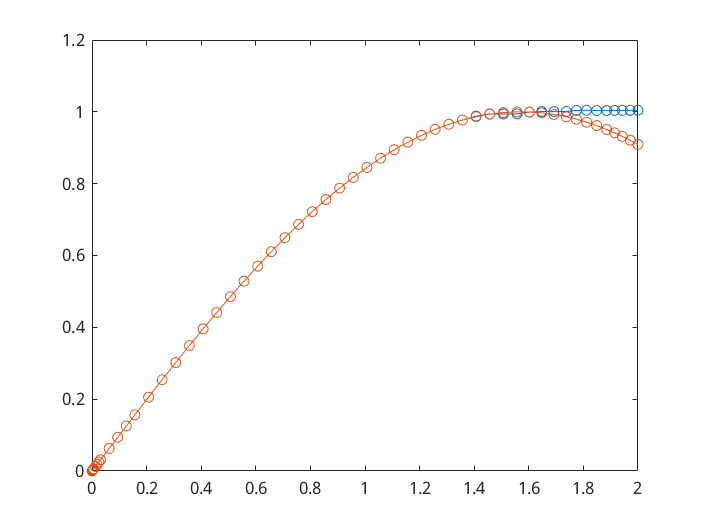

plot(t,y,'-o',t,sin(t),'-o') 

% 2.
% При b > pi/2 нельзя построить отрезок Пеано, 
% y -> inf.

b = 3.14 / 2;
tspan = [0 b];
y0 = 0;
% метод Рунге -- Кутты 4-го порядка
[t,y] = ode45(@(t,y) y^2+1, tspan, y0);  

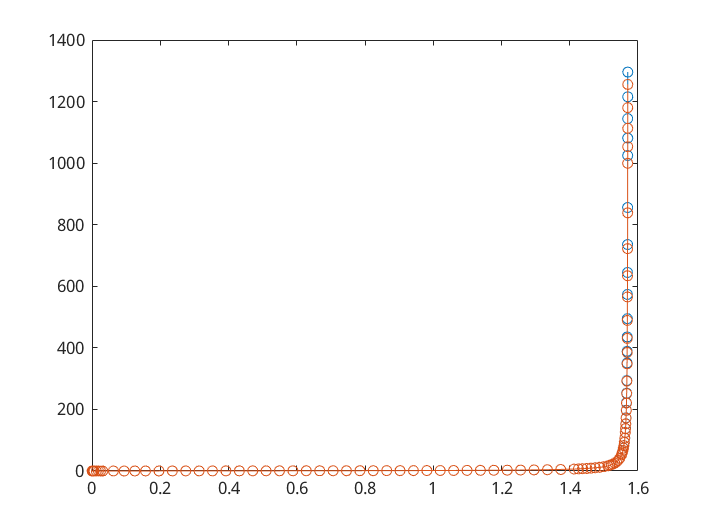

plot(t,y,'-o',t,tan(t),'-o') 

% 3.
% расходится при заданных условиях, т.к. решение не единственное
% (следует из условия Липшица),
% но сходится при смещении константы исходного уравнения 
% или начального условия на малое число.

b = 1;
tspan = [0 b];
y0 = 0;
% метод Рунге -- Кутты 4-го порядка
[t,y] = ode45(@(t,y) y^(1/3)+0.0000000000000001, tspan, y0);  

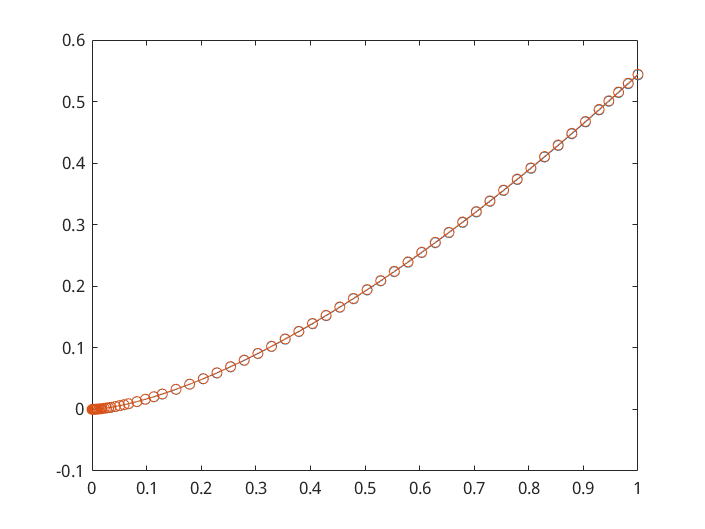

plot(t,y,'-o',t,(2/3)*sqrt(2/3)*(t.^(3/2)),'-o') 